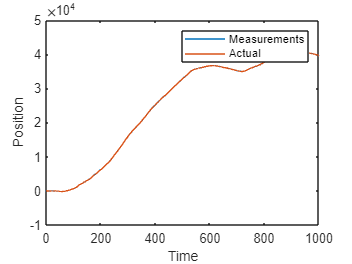

rng(10);
end_time=1000;
dt=0.001;
pts=(end_time/dt)+1;
%Kalman Filter simulation
sw=0.1;
sv=10;

%System
x0=[0 0];
f=zeros(pts,1);
for j=1:length(f)
    f(j)=100*sin(pi*j/200);
end
Ft=[1 dt;0 1];
Bt=[dt^2/2;dt];
H=[1 0];
xt=zeros(length(f)+1,2);
xg=xt;
t=zeros([length(f),1]);
for j=2:length(f)
    t(j)=(j-1)*dt;
end
for i=1:length(f)
    xg(i+1,:)=(Ft*(xt(i,:)')+Bt*f(i))';
    xt(i+1,:)=xg(i+1,:)+normrnd(0,sw,[1,2]);
end
%Measurement
for i=1:length(f)
    zt(i)=H*xt(i,:)'+normrnd(0,sv);
end
%Filter and estimates
x_apr=zeros(size(xt,1)-1,size(xt,2));
x_apost=zeros(size(xt,1)-1,size(xt,2));
P_apost=[0 0;0 0];
initial_s=5;
x_apost(1,:)=x0+normrnd(0,initial_s,[1,2]);
Rt=50;
Qt=[1 0;0 1];
%Uncomment lines 41 and 42 to change the model used for estimation
%Ft=Ft+[0.00001 0; 0 0.00001];
%H=H+[0.00001 0];
for i=1:size(x_apost)-1
    %Prediction update
    x_apr(i+1,:)=Ft*(x_apost(i,:)')+Bt*f(i+1);
    P_apr=Ft*P_apost*Ft'+Qt;
    %Measurement update
    Kt=P_apr*(H')*inv(H*P_apr*(H')+Rt);
    x_apost(i+1,:)=x_apr(i+1,:)+(Kt*(zt(i+1)-H*(x_apr(i+1,:)')))';
    P_apost=P_apr-Kt*H*P_apr;
end

plot(t,zt(1:length(xt)-1));
hold on;
plot(t,xg(1:length(xt)-1,1));
legend('Measurements','Actual');
xlabel('Time');
ylabel('Position');
hold off;

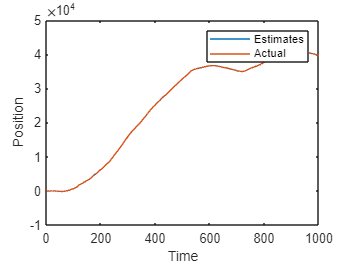

plot(t,x_apost(1:length(xt)-1,1));
hold on;
plot(t,xg(1:length(xt)-1,1));
legend('Estimates','Actual');
xlabel('Time');
ylabel('Position');
hold off;

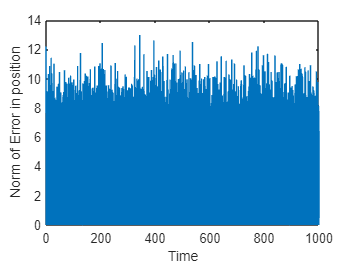

plot(t,sqrt((xg(1:length(xt)-1,1)-x_apost(1:length(xt)-1,1)).^2));
xlabel('Time');
ylabel('Norm of Error in position');

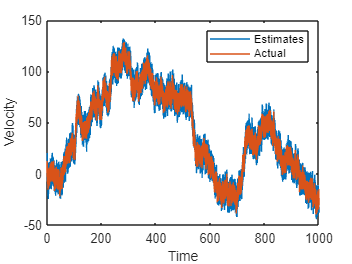

plot(t,x_apost(1:length(xt)-1,2));
hold on;
plot(t,xg(1:length(xt)-1,2));
legend('Estimates','Actual');
xlabel('Time');
ylabel('Velocity');
hold off;

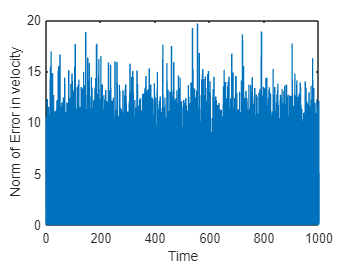

plot(t,sqrt((xg(1:length(xt)-1,2)-x_apost(1:length(xt)-1,2)).^2));
xlabel('Time');
ylabel('Norm of Error in velocity');